**The simulations of the viral infection.**

**For Figure 6b.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

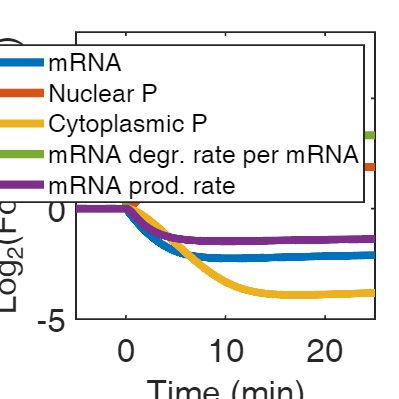

para0=para_opt;

% Modify the paramters
para0(5)=para_opt(5)*20;

k0=para0(1);
am=para0(5);
ax=para0(6);
ay=para0(7);
bx=para0(9);
bm=para0(8);
Kx=para0(2);
Km=para0(4);
Vn=2.8;
Vc=37.2;
Ky=para0(3);
Xt=para0(10);
Yt=para0(11);
Kv=5.8262;
Kp=5e2;
bp=0.5;

para1=[para0,Vn,Vc,Kv,Kp,bp];


% Initialization
mn0=2.23e3;
mc0=8.41e3;
Xn0=5e3;
Xc0=224730;
Xp0=270;
Yn0=964;
Yp0=10036;
Pn0=1e3;
Pnb0=mn0;
Pc0=1e3;
Pcb0=mc0;
y_ini=[mn0,mc0,Xn0,Xc0,Xp0,Yn0,Yp0,Pn0,Pnb0,Pc0,Pcb0];


% Calculate the homeostatic values
tspan=[1:0.01:3e2];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
y_ini2=y_tot(end,:);


% Increase bm mimicking viral infection
para2=para1;
para2(8)=para1(8)*10;

% Calculate the values after infection
tspan=[1:0.01:3e2];
[~,y_tot2]=ode15s(@(t,y)diffun(y,para2),tspan,y_ini2);

y_all=[y_tot(end-1e3:end,:);y_tot2(1:1e4,:)];
%y:[mn mc Xn Xc Xp Yn Yp Pn Pnb Pc Pcb]
mn=y_all(:,1);
mc=y_all(:,2);
m_all=mn+mc;

Xp=y_all(:,5);
Yp=y_all(:,7);
Pn=y_all(:,8);
vpro=(k0*Vn./(Vn+Kv)).*...
    (Xp./(Xp+Kx*Vn)).*...
    Vn*Km./(Vn*Km+mn).*...
    Yp./(Yp+Ky*Vn).*...
    Vn*Kp./(Vn*Kp+Pn);

vdeg1st=[para1(8)*y_tot(end-1e3:end,4)/Vc;...
    para2(8)*y_tot(1:1e4,4)/Vc];

Pn_all=y_all(:,8)+y_all(:,9);

Pc_all=y_all(:,10)+y_all(:,11);


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

scale_time=[(1:length(m_all))-1e3]/100;
p1=plot(scale_time,log2(m_all/m_all(1)),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","mRNA");
hold on
p2=plot(scale_time,log2(Pn_all/Pn_all(1)),'-', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Nuclear P");
hold on
p3=plot(scale_time,log2(Pc_all/Pc_all(1)),'-', ...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","Cytoplasmic P");
hold on
p4=plot(scale_time,log2(vdeg1st/vdeg1st(1)),'-', ...
    "LineWidth",5, ...
    "Color",colors(5),...
    "DisplayName","mRNA degr. rate per mRNA");
p5=plot(scale_time,log2(vpro/vpro(1)),'-', ...
    "LineWidth",5, ...
    "Color",colors(4),...
    "DisplayName","mRNA prod. rate");
hold on
hold off
xlim([-5,25])
ylim([-5,8])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3 p4 p5],"Interpreter","tex","FontSize",15)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Log_2(Fold change)','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp Pn Pnb Pc Pcb]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);
Pn=y(8);
Pnb=mn;
Pc=y(10);
Pcb=mc;

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv Kp bp]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Vn=para(12);
Vc=para(13);
Kv=para(14);
Kp=para(15);
bp=para(16);

dydt = zeros(11,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt dPndt dPnbdt dPcdt dPcbdt]


kn=(k0*Vn/(Vn+Kv))*...
    (Xp/(Xp+Kx*Vn))*...
    Vn*Km/(Vn*Km+mn)*...
    Yp/(Yp+Ky*Vn)*...
    Vn*Kp/(Vn*Kp+Pn);


dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

% ODE of the third protein P
dydt(8)=Pc*bp-kn;%dpndt
dydt(9)=kn-am*(Yn/Vn)*Pnb;%dpnbdt
dydt(10)=bm*(Xc/Vc)*mc-Pc*bp;%dpcdt
dydt(11)=am*(Yn/Vn)*Pnb-bm*(Xc/Vc)*mc;%dpcbdt

end
